# Lab 4

This lab focuses on morphological operators. This is the full list of morphological operations:

- `imerode`

- `imdilate`

- `imopen`

- `imclose`

- `imtophat`

- `imbothat`

- `imclearborder`

- `imkeepborder`

- `imfill`

- `bwhitmiss`

- `bwmorph`

- `bwmorph3`

- `bwperim`

- `bwskel`

- `bwulterode`

`> `Review these functions and identify their roles and why they might be useful

## Task 1: Dilation and Erosion

### Dilation

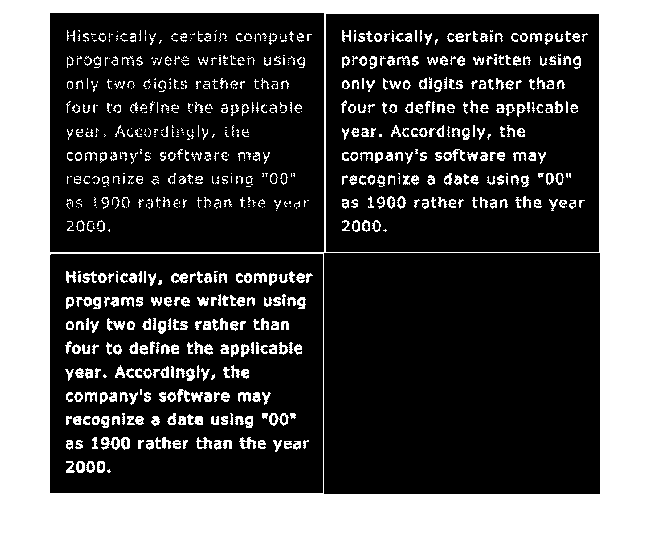

A = imread('inputs/text-broken.tif');
B1 = [0 1 0;
     1 1 1;
     0 1 0];    % create structuring element
A1 = imdilate(A, B1);
A2 = imdilate(A1, B1);
montage({A,A1, A2})

Using a structuring element of all ones:

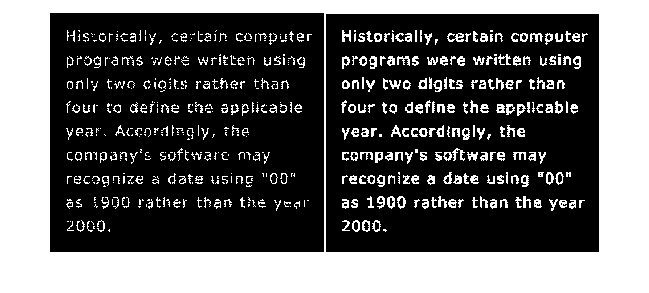

B2 = ones(3,3);     % generate a 3x3 matrix of 1's

A2 = imdilate(A, B2);
montage({A,A2})

This increases the dilation effect as the structuring element occupies more space.

Increasing the size of the structuring element:

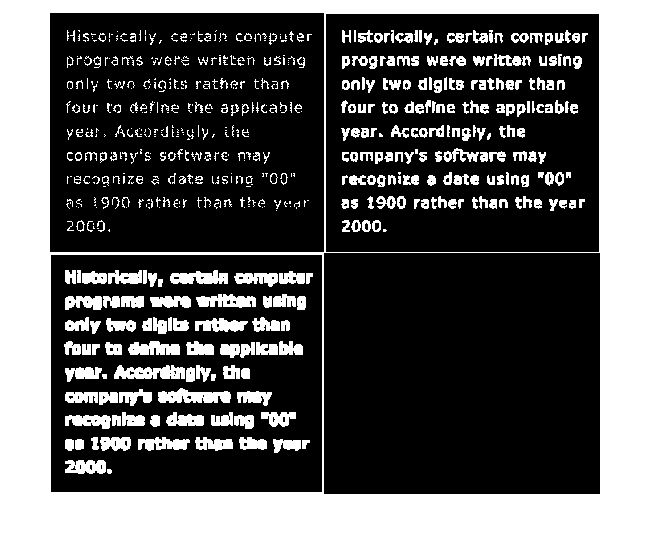

B3 = ones(5,5);    
B4 = ones(10,10);

A3 = imdilate(A, B3);
A4 = imdilate(A, B4);
montage({A,A3, A4})

It can be seen increasing the size of the structuring element increases the dilation effect, making the text appear thicker and eventually illegible - this suggests finding the correct SE size is quite important e.g. if the task was to improve text legibility.

Using a SE diagonal cross:

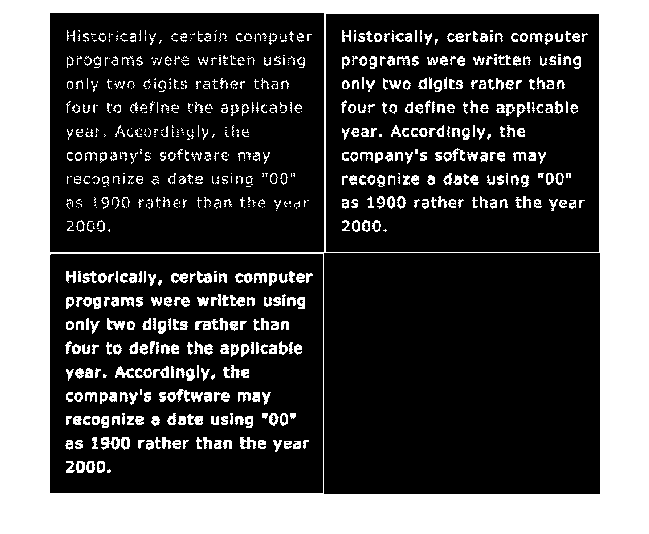

Bx = [1 0 1;
      0 1 0;
      1 0 1];

Bxx = [1 0 0 0 1;
       0 1 0 1 0;
       0 0 1 0 0;
       0 1 0 1 0;
       1 0 0 0 0];
% by increasing the size of the structuring element we can better observe
% the effect of the cross element 

Ax = imdilate(A, Bx);
Axx = imdilate(A, Bxx);
montage({A, Ax, Axx});

What happens if you dilate the original image with B1 twice (or more times)?

This increases the dilation effect - in a similar way to increasing the size of the structuring element.

### Generation of Structuring Element

For spatial filtering, we used function `fspecial` to generate our filter kernel. For morphological operations, we use function *strel* to generate different kinds of structuring elements.

List of SE that `strel` can generate:

- `SE = strel ("diamond", r)`

- `SE = strel("disk", r)`

- `SE = strel("disk", r,n)`

- `SE = strel ("octagon", r)`

- `SE = strel("line", len, deg)`

- `SE = strel("rectangle", [m n] )`

- `SE = strel("square", w)`

> What is the difference between using `strel` and a user-defined SE matrix? 

There is a difference between their internal structures

> What might these different structuring elements be used for?

*strel* returns not a matrix, but an internal data structure called *strel*. This speeds up the execution of the morphological functions by Matlab.

> Are there any other reasons to use `strel` other than for execution speed? 

Strel is better for using a true disk shape etc.

> What does the internal data structure look like?

SE = strel('disk',4);
SE.Neighborhood         % print the SE neighborhood contents

> What is meant by Neighbourhood here? Will this be a smaller ratio if we use a larger SE?

- As the size increases the neighbour still seems to print the entire data structure:

SE = strel('disk',10);
SE.Neighborhood         % print the SE neighborhood contents

### Erosion Operation

A = imread('assets/wirebond-mask.tif');
SE2 = strel('disk',2);

   1   1   1
   1   1   1
   1   1   1



SE10 = strel('disk',10);
SE20 = strel('disk',20);
E2 = imerode(A,SE2);
E10 = imerode(A,SE10);
E20 = imerode(A,SE20);
montage({A, E2, E10, E20}, "size", [2 2])

As the disk size increases more erosion occurs meaning more positive parts of the image, represented by a binary value of 1 are removed, as a fewer proportion of sections (particularly thin, fine or very small sections) meet the criteria to pass the structuring element conditions (i.e. all pixels within the structuring element overlay being equal to 1]. This means increasing disk size removes more components in the image, starting with smaller components and removing larger components as disk size increases.

## Task 2 - Morphological Filtering with Open and Close

Opening = Erosion + Dilation

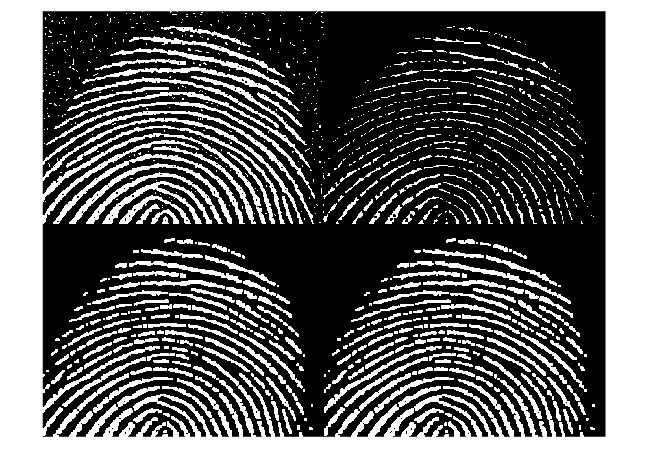

f = imread('inputs/fingerprint-noisy.tif');

% the goal is to generate a 3x3 structuring element SE
% we cab define that with a basic ones matrix:

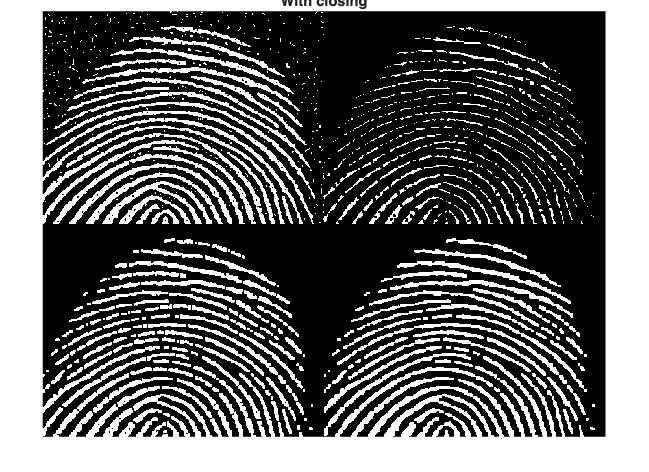

SE = ones(3,3);     % generate a 3x3 matrix of 1's

% but to improve processing speeds we may also want to use strel, for a 3x3
% strel we could use SE = strel("square", w); where w=3 and we can display
% the neighbourhood to confirm this is true


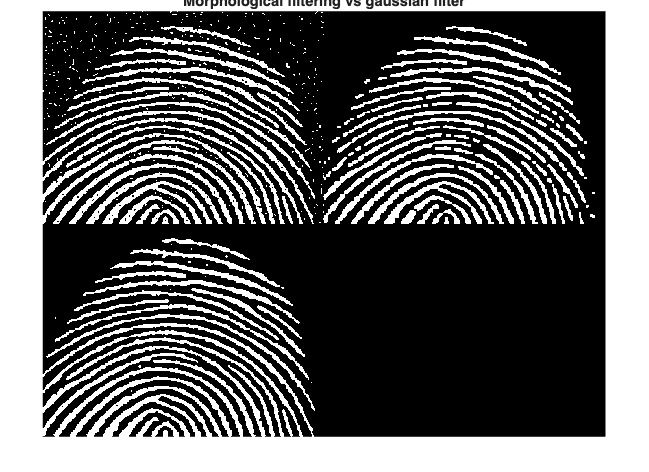

SE_strel = strel("square", 3);
disp(SE_strel.Neighborhood);

fe = imerode(f,SE);
fed = imdilate(fe,SE);
% this process in itself should be opebibf as it is erosion + dilation, but
% we can also use the built in function imopen and we can compare if there
% are any differences


fo = imopen(f,SE);
% we can see the effect looks nearly identical

montage({f, fe, fed, fo});

Eroding first removes some of the positive parts of the image - which can be helpful with removing noise. Dilating then enables us to bring back thickness to the original fingerprint lines without the original salt and pepper noise. Using the built in open function should have the identical effect. 

We can then improve `fo` using a close operation:

fc = imclose(fo,SE);
figure;
montage({f, fe, fo, fc});
title("With closing")

This helps to close any remaining gaps between the fingerprint lines.

Comparing morphological filtering with applying a Gaussian filter:

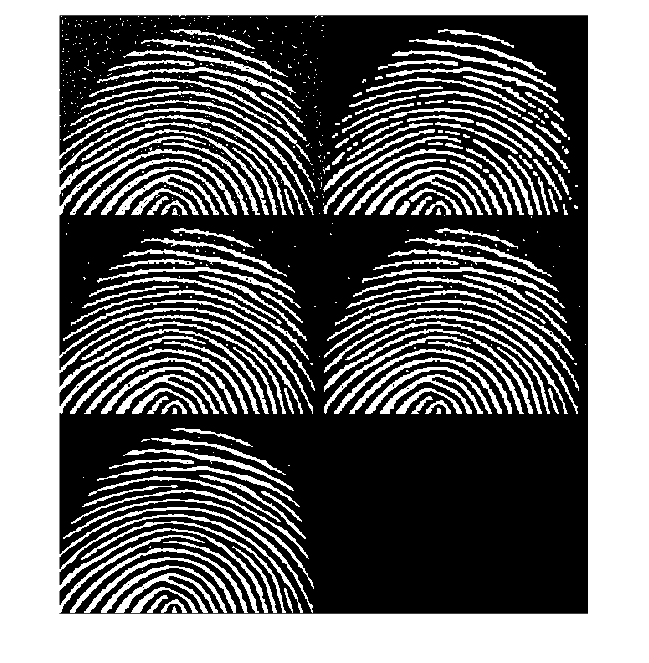

w_gauss = fspecial('Gaussian', [7 7], 1.0);

g_gauss = imfilter(f, w_gauss, 0);

figure;
montage({f, fc, g_gauss});
title("Morphological filtering vs gaussian filter")

A guassian filter is a linear operation - which uses filter kernels. It can be considered a lowpass filter. 

We can see here that the opening, followed by closing morphological operation is more successful at removing noise in this instance than the selected gaussian filter. We can compare to other gaussian kernels:

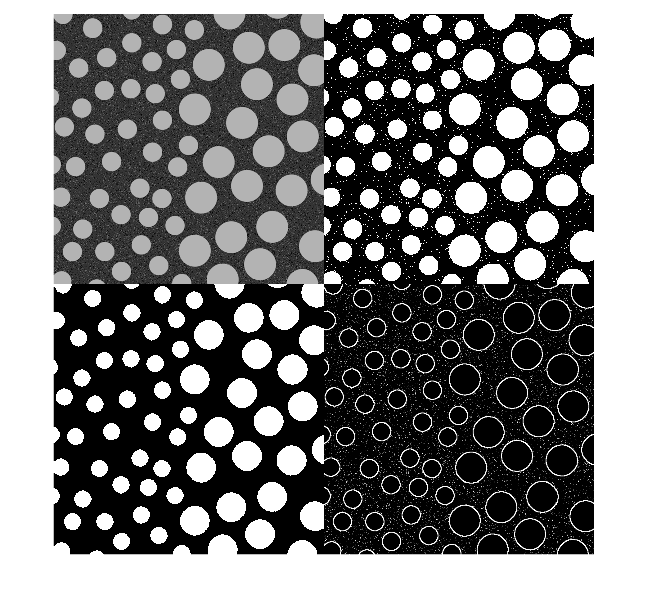

w1 = fspecial('Gaussian', [7 7], 0.8);
w2 = fspecial('Gaussian', [3 3], 1.0);
w3 = fspecial('Gaussian', [40 40], 1.0); 
% significantly increasing the size can remove more noise but there is still remaining noise 
% there might also be the potential of removing parts of the fingerprint we
% may want?

g1 = imfilter(f, w1, 0);
g2 = imfilter(f, w2, 0);
g3 = imfilter(f, w3, 0);


montage({f, fc, g1, g2, g3});

Gaussian filtering can also cause blurring with larger kernels, however blurring does not occur with morphological operations - rather some of the structure may be removed. 

## Task 3 - Boundary Detection

The grayscale image 'blobs.tif' consists of blobs or bubbles of different sizes in a sea of noise. Further, the bubbles are dark, while the background is white. The goal of this task is to find the boundaries of the blobs using the boundary operator (Lecture 6, slide 17).

I = imread('inputs/blobs.tif');
I = imcomplement(I);
level = graythresh(I);
BW = imbinarize(I, level);

SE = strel('disk',3);
eBW = imerode(BW,SE);
new = BW-eBW;
imwrite(new, 'outputs/lab-4-boundary-detection.png');

montage({I, BW, eBW, new});

The Matlab function *graythresh* computes a global threshold *level* from the grayscale image I, by finding a threshold that minimizes the variance of the thresholded black and white pixels. (This method is known as the [Otsu's method](https://cw.fel.cvut.cz/b201/_media/courses/a6m33bio/otsu.pdf).) The function *imbinarize* turns the grayscale image to a binary image BW: those pixels above or equal to *level* are made foreground (i.e. 1), otherwise they are background (0).

The result is not very good because of the noise. It can be improved:

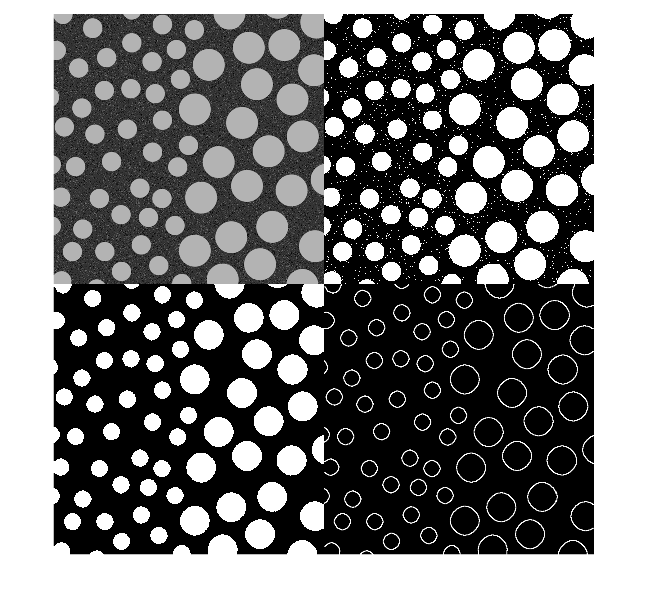

I = imread('inputs/blobs.tif');

I = imcomplement(I);
level = graythresh(I);
BW = imbinarize(I, level);

SE = strel('disk',3);
eBW = imerode(BW,SE);

eBW2 = imerode(eBW,SE);
new = eBW-eBW2;
imwrite(new, 'outputs/lab-4-better-boundary-detection.png');

montage({I, BW, eBW, new});

This result is better ^

What would be even better is doing a opening operation as this current approach shrinks the boundaries a bit, this should rebuild the boundaries.

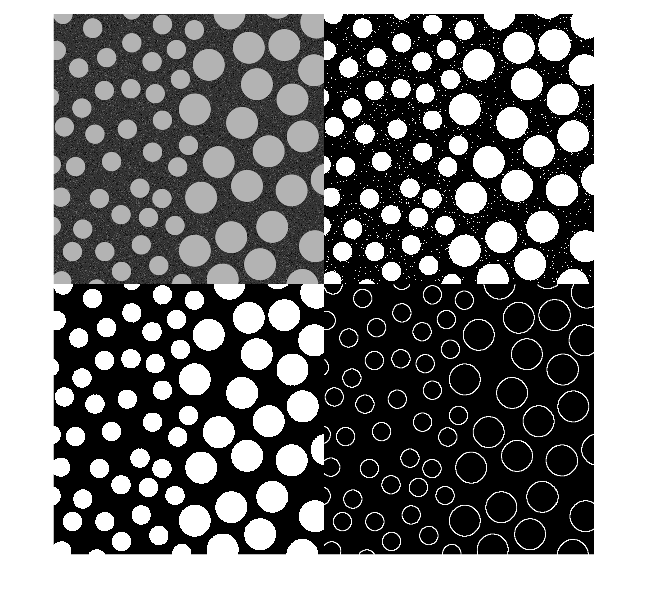

I = imread('inputs/blobs.tif');
I = imcomplement(I);
level = graythresh(I);

BW = imbinarize(I, level);

SE = strel('disk',3);
eBW = imopen(BW,SE);

eBW2 = imerode(eBW,SE);
new = eBW-eBW2;
imwrite(new, 'outputs/lab-4-best-boundary-detection.png');

montage({I, BW, eBW, new});

## Task 4 - Function bwmorph - thinning and thickening

Matlab's Image Processing Toolbox includes a general morphological function *bwmorph* which implements a variety of morphological operations based on combinations of dilations and erosions. The calling syntax is:

`g = bwmorph(f, operations, n)`

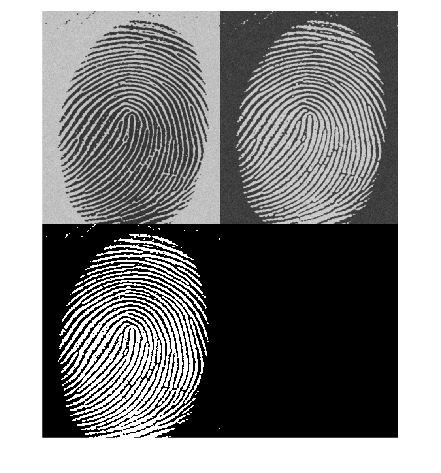

Im = imread('inputs/fingerprint.tif');

I = imcomplement(Im);
level = graythresh(I); 
BW = imbinarize(I, level); %binarising the image

g1 = bwmorph(BW, "thin", 1);
imwrite(g1, 'outputs/lab-4-fingerprint.png');
g2 = bwmorph(BW, "thin", 2);
g3 = bwmorph(BW, "thin", 3);
g4 = bwmorph(BW, "thin", 4);
g5 = bwmorph(BW, "thin", 5);

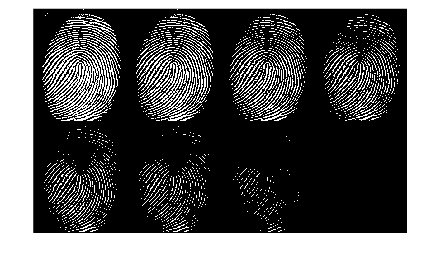

ginf = bwmorph(BW, "thin", inf);

g6 = bwmorph(BW, "thin", 6);
g8 = bwmorph(BW, "thin", 8);
imwrite(ginf, 'outputs/lab-4-fingerprint-thinning.png');

montage({Im, I, BW});
montage({g1, g2, g3, g4, g5, g6, g8, ginf});

Continuing to thin an image will eventually remove a large amount of detail and structure. In this case the fingerprint can be thinned to the minimal amount until further thinning would remove any of the remaining features. 

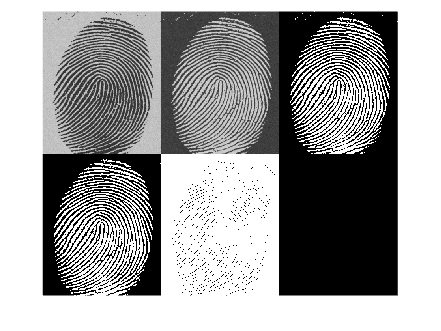

Im = imread('inputs/fingerprint.tif');
I = imcomplement(Im);
level = graythresh(I);
BW = imbinarize(I, level);

se = ones(5,5);
fo = imopen(BW, se); %we can perform opening to try remove a bit of noise


g1 = bwmorph(fo, "thicken", inf); %
imwrite(g1, 'outputs/lab-4-fingerprint-thickening.png');

montage({Im, I, BW, fo, g1});

doing inf thickening will produce the black image instead on a white background instead.

Thickening and thinning have a relationship between each other (thickening is the dual/opposite of thinning). 

## Task 5 - Connected Components and labels

The goal in this task is to find the largest connected component in the image and erase it. 

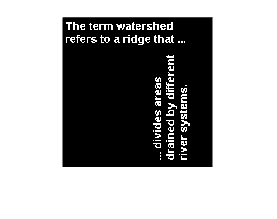

t = imread('inputs/text.png');
imshow(t)

CC = bwconncomp(t)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 88
    PixelIdxList: {1×88 cell}


To determine which is the largest component in the image and then erase it (i.e. set all pixels within that componenet to 0), do this:

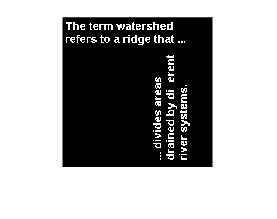

numPixels = cellfun(@numel, CC.PixelIdxList); 
% we are able to find the number of pixels in each connected component

[biggest, idx] = max(numPixels); %finding the connected component with the maximum number of pixels
t(CC.PixelIdxList{idx}) = 0; %setting the values to zero
figure
imshow(t)

The two ffs in different are removed from the image

`PixelIdList` - 1-by -NumObjects cell array where the th element in the ell array is a vector containing the linear indices of the pixels in the k-th connected component.

## Task 6 - Morphological Reconstruction

In morphological opening, erosion typlically removes small objects, and subsequent dilation tends to restore the shape of the objects that remains. However, the accuracy of this restoration relies on the similarly between the shapes to be restored and the structuring element.

*Morphological reconstruction* (MR) is a better method that restores the original shapes of the objects that remain after erosion.

MR uses:

- Mask

- Marker image

- Structuring element

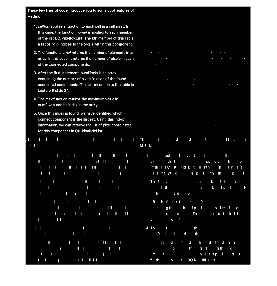

clear all
close all
f = imread('inputs/text_bw.tif');
se = ones(17,1);
g = imerode(f, se);
fo = imopen(f, se);     % perform open to compare
fr = imreconstruct(g, f);
montage({f, g, fo, fr}, "size", [2 2])

Marker (Image) is eroded with structuring element (SE). The structuring element is 17x1 because the long vertical elements are 17 pixels tall. Reconstruction is used with g and f. 

- Image 1 is the unaffected text.

- Image 2 is the text eroded away to only include the seeds for the letters with tall vertical elements.

- Image 3 - the eroded elements are opened up, this restores tall vertical elements (17 pixels tall) but it is not possible to restore the original letter shapes.

- Image 4 - because this uses the reconstruction with `g` the original tall letters are able to be reconstructed without restoring the shorter letters (as their seeds were removed)

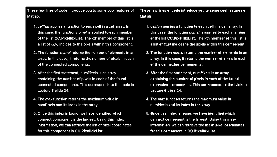

ff = imfill(f);
figure
montage({f, ff})

Holes in the text are filled for example in the word "Open" the O becomes filled.

## Task 7 - Morphological Operations on Grayscale images

Erosion and dilation on grayscale images

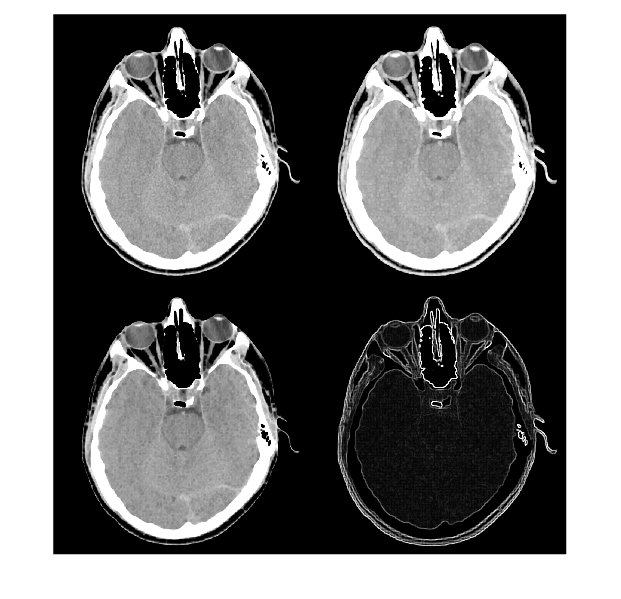

clear all; close all;
f = imread('inputs/headCT.tif');
se = strel('square',3);
gd = imdilate(f, se);
ge = imerode(f, se);
gg = gd - ge;
montage({f, gd, ge, gg}, 'size', [2 2])

- In the dilated result some of the structures have been thickened e.g. particuarly around the nose region.

- In the eroded result some of the structures have been thinned, particularly the finer details such as the outer skull.

- `gg` shows the difference between the dilated result and eroded result which produces a boundary outline. Subtracting an eroded image from a dilated image enables extraction of the morphological gradient - this is somewhat similar to other operations like sobel. 

We can compare `gg` with a sobel operation:

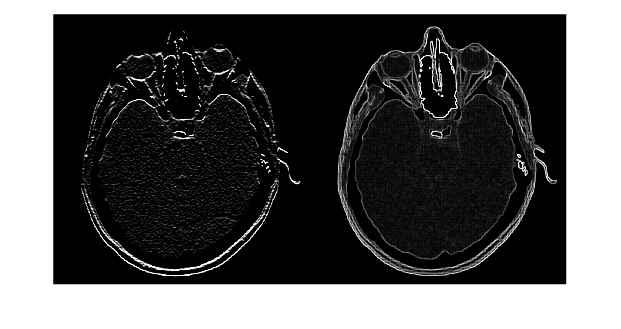

h = fspecial('sobel');
s1 = imfilter(f, h);

montage({s1, gg})

They are similar but the morphological operation preserves more detail and overall looks higher quality.

# Challenges 1-3 are in `challenges.mlx`